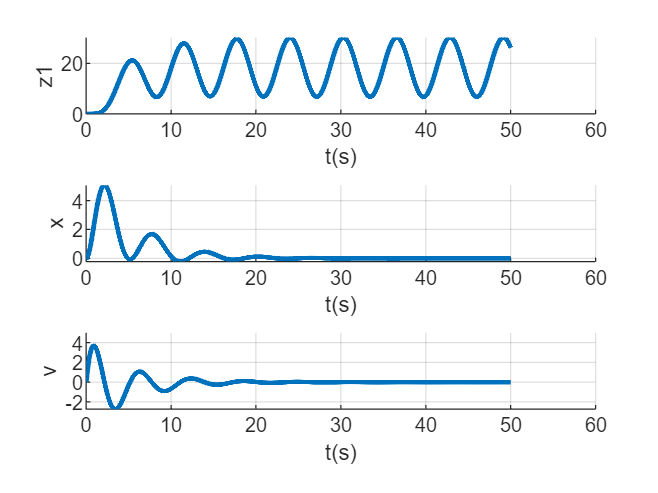

%% 参数设置
close all,clear,clc,

global m Omega
m = 1;
Omega = 1;

% 外部交变干扰
a = 5;
phi = 30*pi/180;
f0 = 6;

t0 = 0.0;
dt = 0.01;
tf = 50;
tout = t0:dt:tf;

x0 = 0; %初始位置
v0 = 0; %初始速度

z1 = 0;
z2 = 0;
z3 = 0;
z4 = x0;
z5 = v0;
state = [z1;z2;z3;z4;z5];
stateout = state;

uout = [];
fout = [];

A = [0 1 0 0 0;
     0 0 1 0 0; 
     0 -Omega^2 0 1 0;
     0 0 0 0 1;
     0 0 0 0 0];
B = [0; 0; 0; 0; 1/m];
lambda = [-0.2+i; -0.2-i; -0.5+i; -0.5-i; -0.25];
K = place(A, B, lambda);
%% 仿真
for t = t0:dt:tf
    f = a*sin(Omega*t+phi) + f0;
    fout = [fout, f];

    u = -K*state;
    uout = [uout, u];
    ke1 = stateequation(t, state, u, f);
    ke2 = stateequation(t+0.5*dt, state+0.5*ke1*dt, u, f);
    ke3 = stateequation(t+0.5*dt, state+0.5*ke2*dt, u, f);
    ke4 = stateequation(t+dt, state+ke3*dt, u, f);
    state = state + 1/6*(ke1 + 2*ke2 + 2*ke3 + ke4)*dt;
    stateout = [stateout, state];
end

z1out = stateout(1, :);
z2out = stateout(2, :);
z3out = stateout(3, :);
z4out = stateout(4, :);
z5out = stateout(5, :);
tout = [tout, tout(end)+dt];
fout = [fout, fout(end)];
uout = [uout, uout(end)];

%% 绘图
figure(1);
subplot(3,1,1);
hold on;grid on;
plot(tout, z1out, 'LineWidth', 2);
xlabel('t(s)');ylabel('z1');

subplot(3,1,2);
hold on;grid on;
plot(tout, z4out, 'LineWidth', 2);
xlabel('t(s)');ylabel('x');

subplot(3,1,3);
hold on;grid on;
plot(tout, z5out, 'LineWidth', 2);
xlabel('t(s)');ylabel('v');

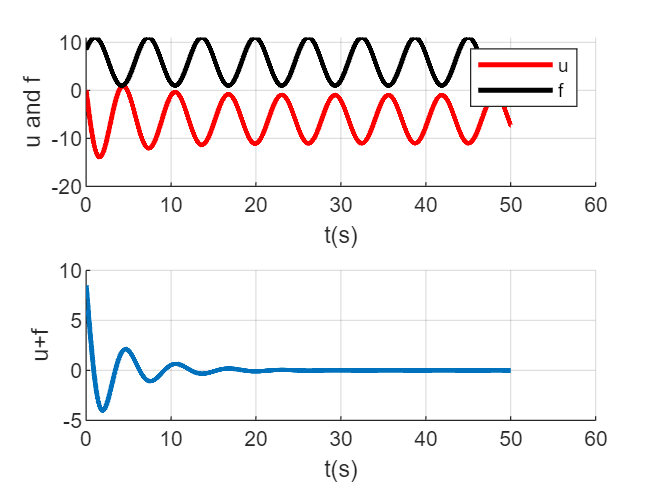


figure(2);
subplot(2,1,1);
hold on;grid on;
plot(tout, uout, 'Color', 'red', 'LineWidth', 2);
plot(tout, fout, 'Color', 'black', 'LineWidth', 2);
xlabel('t(s)');ylabel('u and f');
legend("u","f")

subplot(2,1,2);
hold on;grid on;
plot(tout, uout + fout, 'LineWidth', 2);
xlabel('t(s)');ylabel('u+f');

function statedot=stateequation(t,state, u, f)
global m Omega
% state = [z1,z2,z3,z4,z5];
z1 = state(1);
z2 = state(2);
z3 = state(3);
z4 = state(4);
z5 = state(5);

%状态方程
z1dot = z2;
z2dot = z3;
z3dot = -Omega^2*z2+z4;
z4dot = z5;
z5dot = 1/m*(u+f);

%输出得到的四个状态量
statedot=[z1dot;z2dot;z3dot;z4dot;z5dot];
end